## Initialize the class

Initialize with an equilibrium point $\phi_{eq}$, a tolerance $\Delta\phi$ and a vector of string $\phi_{str}$ that names the variable (for plotting purposes). All the three vectors must have the same size. You can change the default values for the solver used and the verbose parameter of the optimization calls.

vanderpol = SOStab([0;0], [1.1;1.1]);
%vanderpol.solver = 'mosek';
%vanderpol.verbose = 2;

## Define the dynamic of the system

Define $f$ such that $\dot{\phi} = f(\phi)$ the vector must have the same size as $\phi$. The property "phi" of the system is a Yalmip sdpvar, which is a symbolic representation of the state variable. It has the same size as the problem.

For example, here we implement $f$ such that $\dot{\phi}_1 = -2\phi_2$ and $\dot{\phi}_2 = 0.8\phi_1 + 10(\phi_1^2 - 0.21)\phi_2$.

vanderpol.dynamics=[-2*vanderpol.x(2); 
    0.8*vanderpol.x(1) + 10*(vanderpol.x(1)^2-0.21)*vanderpol.x(2)];

## Solve the outer approximation problem

Solve the outer approximation of the finite horizon ROA for a target set $K = \{ \phi | \|A(\phi - \phi_{eq} \| \leq \epsilon \}$ and a horizon $T$. The degree of the polynomials is defined by $d$. $d$ above 20 is useless and for high dimensions, a standard computer RAM can't cope with $d$ above 10.

A = eye(2);
epsilon = 0.5;
d = 16;
T = 1;
[sol, vc, wc] = vanderpol.SoS_out(d, T, epsilon, A);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 3762 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/12
Initially 36 monomials in R^2
Removing large/small............Keeping 36 monomials (0.02sec)
Newton polytope (0 LPs).........Keeping 36 monomials (0.05sec)
Finding symmetries..............Found no symmetries (0.01sec)
Creating SOS-description 2/12
Initially 45 monomials in R^2
Removing large/small............Keeping 45 monomials (0sec)
Newton polytope (0 LPs).........Keeping 45 monomials (0.02sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 3/12
Initially 36 monomials in R^2
Removing large/small............Keeping 36 monomials (0sec)
Newton polytope (0 LPs)........

## Solve the inner approximation problem

Solve the inner approximation of the ROA. Note that the results of this approximation are very sensitive to the relative size of the sets and the degree of the polynomials. You can check the relevance of the results by verifying the coefficients of wc. If they are null for most of them, then the computation didn't worked. You can try to increase the size of the target set or the degree of the polyomials.

A = eye(2);
epsilon = 0.5;
d = 16;
T = 1;
[sol, vc, wc] = vanderpol.SoS_in(A, epsilon, d, T);

-------------------------------------------------------------------------
YALMIP SOS module started...
-------------------------------------------------------------------------
Detected 6722 parametric variables and 3 independent variables.
Detected 0 linear inequalities, 0 equality constraints and 0 LMIs.
Using kernel representation (options.sos.model=1).
Creating SOS-description 1/18
Initially 36 monomials in R^2
Removing large/small............Keeping 36 monomials (0sec)
Newton polytope (0 LPs).........Keeping 36 monomials (0sec)
Finding symmetries..............Found no symmetries (0sec)
Creating SOS-description 2/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 3/18
Re-using all candidate monomials (same problem structure)
Creating SOS-description 4/18
Initially 45 monomials in R^2
Removing large/small............Keeping 45 monomials (0sec)
Newton polytope (0 LPs).........Keeping 45 monomials (0sec)
Finding symmetries..............Found no symme

## Plot the ROA

Plot the projection of the ROA on two dimensions (for the last calculated approximation).

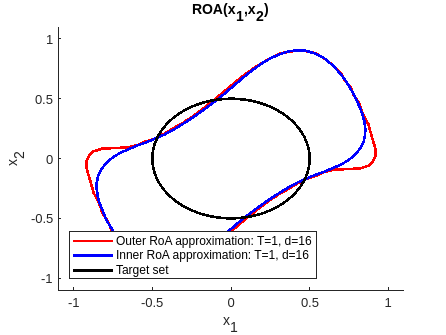

clf;
vanderpol.plot_roa(1,2, 'outer');
vanderpol.plot_roa(1,2, 'inner', 1);

## Plot the surface of $w$

Plot the surface of $w$ for the last calculated inner or outer approximation.

vanderpol.plot_w(1,2, 'i'); % inner ROA
% vanderpol.plot_w(1,2, 'o'); % or outer ROA